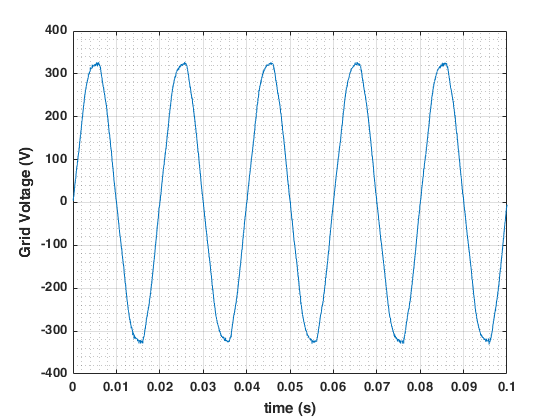

%%% FIRST RUN a.load_data.mlx;

measurement = meas11;  %% no-load
% measurement = meas12;  %% heater
% measurement = meas13;  %% heater + bridge rectifier (w/ inductance)
% measurement = meas14;  %% bridge rectifier (no inductance)

grid_voltage_real = measurement.V_ch1; 
time_vector = measurement.Timestamp;

plot(time_vector, grid_voltage_real);
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

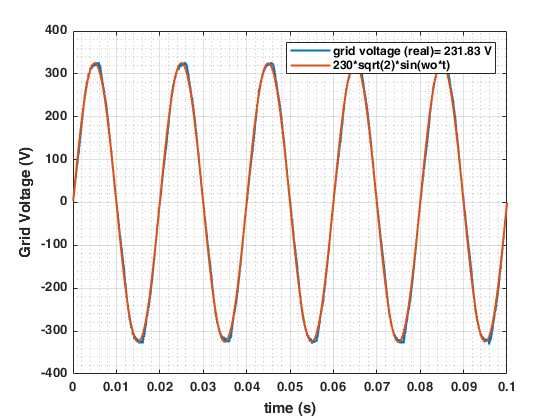


w0 = (50*2*pi());
grid_voltage_expected = 230*sqrt(2)*sin(time_vector.*w0);

plot(time_vector, grid_voltage_real, 'LineWidth', 1.5); 
hold on; plot(time_vector, grid_voltage_expected, 'LineWidth', 1.5); 
legend(strcat("grid voltage (real)= ", num2str(rms(grid_voltage_real), '%.2f'), " V"), "230*sqrt(2)*sin(wo*t)");
xlabel("time (s)"); ylabel("Grid Voltage (V)");
grid on; grid minor;

hold off;

## Spectrum Analysis

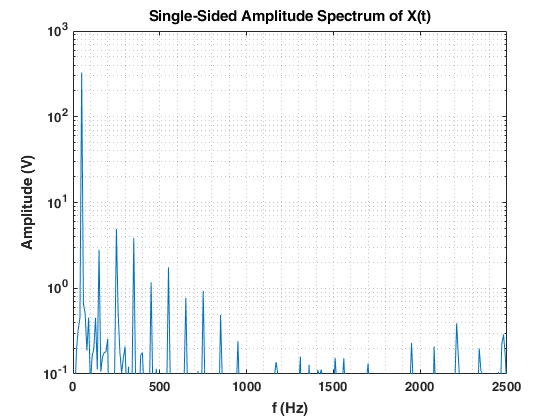

x = grid_voltage_real;
Fs = length(grid_voltage_real)*10;
L = length(x);
Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
semilogy(f,P1); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('Amplitude (V)')
xlim([0 2500]);
ylim([1e-1 1e3]);

## Harmonic analysis

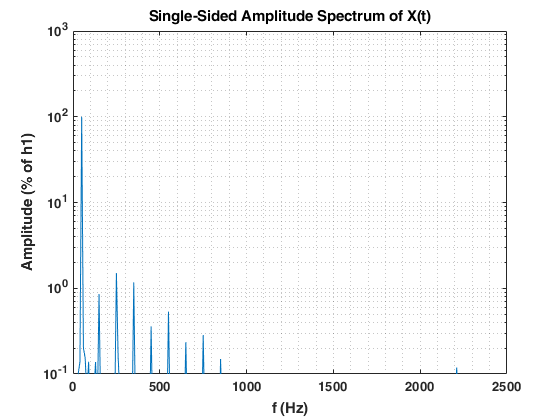

semilogy(f, P1.*(100/P1(6))); grid minor;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('Amplitude (% of h1)')
xlim([0 2500]);
ylim([1e-1 1e3]);

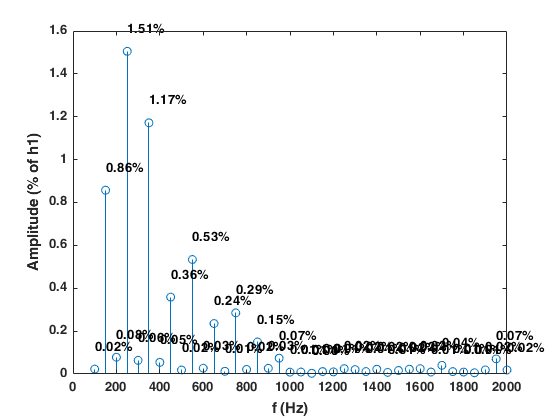

%%% vector of the positions of harmonic frequencies (50 Hz, 100 Hz, ...., 50*40 Hz)
h_vector = ((1:40)*5+1);
f_vector = (1:40).*50;
pp_P1_vector = P1(h_vector).*(100/P1(h_vector(1)));
pp_harmonics = [f_vector' pp_P1_vector];
stem(pp_harmonics(2:end,1), pp_harmonics(2:end,2)); 
hold on; 
text(pp_harmonics(2:end,1), pp_harmonics(2:end,2)+0.1, strcat(num2str(pp_harmonics(2:end,2), '%.2f') , "%") );
xlabel('f (Hz)')
ylabel('Amplitude (% of h1)');


%%%THD = SLIDE 7 of Presentation
THD_grid_voltage = 1/P1(h_vector(1)) * sqrt(sum(P1(h_vector(2:end)).^2));
fprintf("Value of THD: 100 * (V diff)/(V h1) = %.2f %%", THD_grid_voltage * 100);

Value of THD: 100 * (V diff)/(V h1) = 2.23 %

fprintf("Value of 5th harmonic = %.2f %%", (P1(h_vector(5))/(P1(h_vector(1))))*100);

Value of 5th harmonic = 1.51 %

**EN50160:**

Voltage THD: less than 8% (up to 40th harmonic);